# 12주차 — 상태공간 해석: 모드, 가제어성, 가관측성

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지금까지 열한 주 동안 **전달함수**로 일했습니다. 오늘부터 세 주는 **상태공간**으로 일합니다. 3주차에서 잠깐 만났던 그것입니다.

왜 바꾸는가 — 전달함수로는 못 하는 일이 있기 때문입니다.

- 극점을 **원하는 자리에 정확히** 놓기 (13주차)

- 못 재는 상태를 **만들어 내기** (14주차)

오늘은 그 두 가지를 하기 전에 **할 수 있는지 없는지 판정**하는 법을 배웁니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W12_StateSpace_Analysis` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

$A$** 의 고유값이 시스템의 성격을 정하고, 고유벡터가 그 성격이 드러나는 방향을 정한다. 그리고 그 성격을 우리가 바꿀 수 있는지는 **$B$** 와 **$C$** 가 정한다.**

오늘의 계단

- **1~3절** 상태방정식의 해. $e^{At}$ 가 무엇인가

- **4~6절** 모드 — 고유값 하나가 만드는 응답 조각

- **7~9절** 가제어성 — 입력으로 모든 상태를 움직일 수 있는가

- **10~12절** 가관측성 — 출력만 보고 모든 상태를 알 수 있는가

- **13절** 오늘 판정한 것이 다음 두 주의 입장권이다

오늘 딱 하나만 기억한다면 이것입니다.

- **가제어가 아니면 13주차를, 가관측이 아니면 14주차를 할 수 없다**

## 0-1. 가장 작은 예부터 — 지수함수 하나

이해를 돕기 위해 상태가 **하나뿐인** 시스템부터 봅니다.


$$\dot{x} = a\,x, \qquad x(0) = x_0$$


고등학교에서 푼 그 미분방정식입니다. 답은 이렇습니다.


$$x(t) = e^{at}\,x_0$$


여기서 전부가 나옵니다.

- $a < 0$ 이면 줄어든다 (안정)

- $a > 0$ 이면 커진다 (불안정)

- $|a|$ 가 클수록 빠르다

상태가 여러 개면 $a$ 가 행렬 $A$ 가 되고, $e^{at}$ 가 $e^{At}$ 가 됩니다. **모양이 똑같습니다.** 오늘 배우는 것은 이 한 줄을 행렬로 늘리는 일입니다.

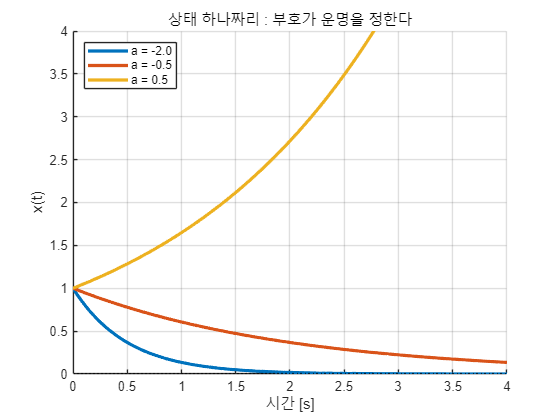

a_list = [-2 -0.5 0.5];
t0 = 0:0.01:4;
hold on; grid on;
for a = a_list
    plot(t0, exp(a*t0), 'LineWidth', 2.4, 'DisplayName', sprintf('a = %.1f', a));
end
yline(0, 'k:', 'HandleVisibility', 'off');
xlabel('시간 [s]'); ylabel('x(t)'); ylim([0 4]);
legend('Location', 'northwest');
title('상태 하나짜리 : 부호가 운명을 정한다');

## 1. 상태방정식의 해

3주차에서 두 줄을 배웠습니다.


$$\dot{x} = Ax + Bu, \qquad y = Cx + Du$$


이 미분방정식의 해는 이렇게 생겼습니다.


$$x(t) = e^{At}\,x(0) + \int_0^t e^{A(t-\tau)}\,B\,u(\tau)\,d\tau$$


복잡해 보이지만 어렵지 않습니다. 두 조각으로 읽으면 됩니다.

- **앞의 항** — 초기조건이 스스로 흘러가는 것. 입력과 무관하다

- **뒤의 항** — 입력이 만든 것. 초기조건과 무관하다

선형 시스템이라 두 효과가 그냥 **더해집니다.** 이것을 중첩이라 합니다.

그리고 $e^{At}$ 를 **상태천이행렬**이라 부릅니다. 이름이 거창하지만 하는 일은 하나입니다 — **지금 상태를 넣으면 **$t$** 초 뒤 상태를 돌려준다.**

## 2. 행렬 지수함수 $e^{At}$ 는 무엇인가

정의는 스칼라 지수함수의 급수를 그대로 흉내 낸 것입니다.


$$e^{At} = I + At + \frac{(At)^2}{2!} + \frac{(At)^3}{3!} + \cdots$$


MATLAB 에서는 `expm(A*t)` 한 줄입니다.

**중요한 주의** — `exp(A)` 와 `expm(A)` 는 완전히 다릅니다.

- `exp(A)` — 행렬의 **각 원소**에 지수함수를 씌운다. 우리가 원하는 것이 아니다

- `expm(A)` — 행렬 지수함수. 이것이 맞다

학생들이 가장 많이 틀리는 지점입니다. 반드시 `m` 을 붙이십시오.

A0 = [0 1; -2 -3];
fprintf('exp(A)  = %s   <- 틀린 것\n', mat2str(round(exp(A0), 4)));

exp(A)  = [1 2.7183;0.1353 0.0498]   <- 틀린 것


fprintf('expm(A) = %s   <- 맞는 것\n', mat2str(round(expm(A0), 4)));

expm(A) = [0.6004 0.2325;-0.4651 -0.0972]   <- 맞는 것


## 2-1. 상태천이행렬의 성질 세 가지

외울 것은 셋뿐이고, 전부 스칼라 지수함수에서 그대로 옮겨 온 것입니다.


$$e^{A\cdot 0} = I \qquad\qquad (e^{At})^{-1} = e^{-At}$$



$$e^{A(t_1+t_2)} = e^{At_1}\,e^{At_2}$$


각각의 뜻

- **첫째** — $0$ 초 뒤의 상태는 지금 상태. 당연합니다

- **둘째** — 시간을 거꾸로 돌릴 수 있다. 선형 시스템이라 가능합니다

- **셋째** — $2$ 초 흐른 것은 $1$ 초 흐르고 또 $1$ 초 흐른 것과 같다

셋째가 "천이" 라는 이름의 근거입니다. 상태가 시간을 따라 **한 자리에서 다음 자리로 옮겨 가는** 것입니다.

**주의** — $e^{At}e^{Bt} = e^{(A+B)t}$ 는 **일반적으로 틀립니다.** $AB = BA$ 일 때만 성립합니다. 행렬은 곱셈 순서가 중요하기 때문입니다.

## 2-2. $e^{At}$ 가 실제로 하는 일

식만 보면 감이 안 옵니다. 그림으로 확인하겠습니다.

$x(t) = e^{At}x(0)$ 에서 $e^{At}$ 는 **초기 상태를 받아 **$t$** 초 뒤의 상태로 보내는 사상**입니다. 시각 $t$ 를 하나 정하면 $e^{At}$ 는 $2\times 2$ 행렬 하나가 되고, 그 행렬을 $x(0)$ 에 곱하면 그 순간의 상태가 나옵니다.

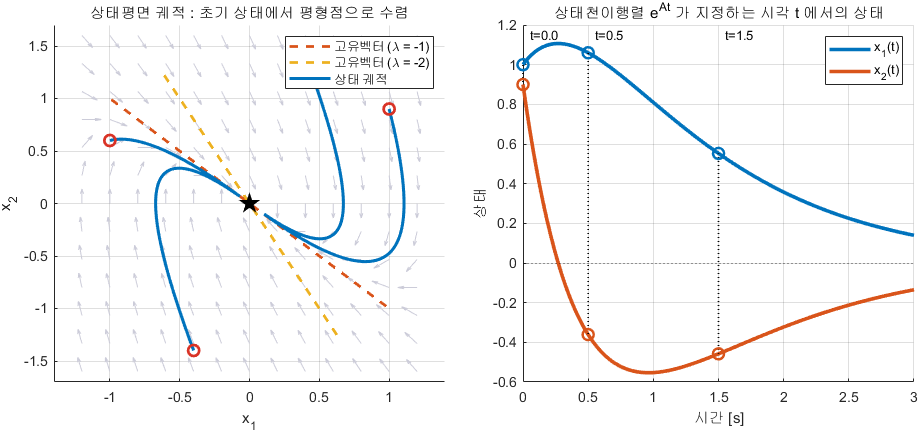

상태천이행렬이 상태를 시간에 따라 옮긴다

**그림 파일** `w12_transition.png` — `make_figures.m` 의 `fig_w12_transition` · 다시 만들려면 `make_figures('w12_transition')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_transition` **직접 확인해 보려면** — `W12_01_state_response.m` 의 **1-1절**이 `expm(A*t)` 로 구한 상태와 `lsim` 결과가 같은지 대조합니다

그림 해석

왼쪽과 오른쪽은 **같은 궤적의 두 표현**입니다. 왼쪽은 시간을 감추고 자취만, 오른쪽은 시간축을 펴서 값을 보여 줍니다.

## 3. 고유값과 고유벡터가 왜 나오는가

$e^{At}$ 를 급수로 계산하는 것은 사람이 할 일이 아닙니다. 그런데 $A$ 가 **대각행렬**이면 이야기가 달라집니다.


$$A = \left[\begin{array}{cc}\lambda_1 & 0\\ 0 & \lambda_2\end{array}\right] \qquad\Rightarrow\qquad e^{At} = \left[\begin{array}{cc}e^{\lambda_1 t} & 0\\ 0 & e^{\lambda_2 t}\end{array}\right]$$


각 원소에 지수함수를 씌우면 끝입니다. **스칼라 문제 두 개로 쪼개진** 것입니다.

그래서 이런 생각을 합니다 — **좌표를 바꿔서 **$A$** 를 대각행렬로 만들 수 없을까?**

그것이 정확히 고유값 분해입니다.


$$A = V\,\Lambda\,V^{-1} \qquad\Rightarrow\qquad e^{At} = V\,e^{\Lambda t}\,V^{-1}$$


- $\Lambda$ — 고유값을 대각선에 놓은 행렬

- $V$ — 고유벡터를 열로 세운 행렬

**고유벡터는 좌표축입니다.** 그 축에서 보면 시스템이 스칼라 문제로 쪼개집니다.

## 3-0. 오른쪽 식이 왜 성립하는가 — 급수에 그대로 넣으면 된다

$e^{At} = V e^{\Lambda t} V^{-1}$ 를 받아 적지 말고 **급수 정의에 넣어** 봅니다. 두 걸음이면 끝납니다.

**첫째 걸음 — **$A$** 의 거듭제곱이 어떻게 되는가.** $A = V\Lambda V^{-1}$ 를 두 번 곱해 봅니다.


$$A^2 = \left(V\Lambda V^{-1}\right)\left(V\Lambda V^{-1}\right) = V\Lambda \left(V^{-1}V\right) \Lambda V^{-1} = V\Lambda^2 V^{-1}$$


**가운데의 **$V^{-1}V$** 가 단위행렬이 되어 지워지는 것**이 핵심입니다. 같은 일이 몇 번을 곱해도 반복되므로


$$A^k = V\,\Lambda^k\,V^{-1} \qquad (k = 0, 1, 2, \ldots)$$


**둘째 걸음 — 급수에 넣는다.** 2절의 정의는 이것이었습니다.


$$e^{At} = I + At + \frac{(At)^2}{2!} + \frac{(At)^3}{3!} + \cdots$$


각 항에 위 결과를 넣습니다. $I = V I V^{-1}$ 로 써 두면 모양이 같아집니다.


$$e^{At} = V I V^{-1} + V\Lambda V^{-1}t + V\frac{\Lambda^2}{2!}V^{-1}t^2 + \cdots$$


**모든 항의 앞뒤에 **$V$** 와 **$V^{-1}$** 이 똑같이 붙어 있으므로 밖으로 묶어냅니다.**


$$e^{At} = V\left(I + \Lambda t + \frac{(\Lambda t)^2}{2!} + \cdots\right)V^{-1} = V\,e^{\Lambda t}\,V^{-1}$$


그리고 $\Lambda$ 는 대각행렬이므로 $e^{\Lambda t}$ 는 **대각선에 지수함수만 놓으면** 됩니다.


$$e^{\Lambda t} = \left[\begin{array}{cc} e^{\lambda_1 t} & 0 \\ 0 & e^{\lambda_2 t}\end{array}\right]$$


**이제 왜 고유값만 보면 안정성을 알 수 있는지도 보입니다.** $e^{At}$ 안에 들어 있는 시간 함수가 $e^{\lambda_i t}$ 뿐이기 때문입니다. 어느 하나라도 $\mathrm{Re}(\lambda_i) > 0$ 이면 그 항이 커지고, 전체가 발산합니다.

아래에서 세 가지를 대조합니다 — `expm`, 급수 직접 계산, 그리고 고유분해.

Ad = [0 1; -2 -3];
[Vd, Dd] = eig(Ad);
td = 0.4;
E_expm  = expm(Ad*td);
E_eigen = real(Vd * diag(exp(diag(Dd)*td)) / Vd);
E_ser   = eye(2);  Tk = eye(2);
for kk = 1:25
    Tk = Tk * (Ad*td) / kk;
    E_ser = E_ser + Tk;
end
fprintf('=== e^{At} 를 세 방법으로 (t = %.1f) ===\n', td);

=== e^{At} 를 세 방법으로 (t = 0.4) ===


fprintf('  expm      : %s\n', mat2str(round(E_expm(:).', 6)));

  expm      : [0.891311 -0.441982 0.220991 0.228338]


fprintf('  급수 25항  : %s\n', mat2str(round(E_ser(:).', 6)));

  급수 25항  : [0.891311 -0.441982 0.220991 0.228338]


fprintf('  고유분해   : %s\n', mat2str(round(E_eigen(:).', 6)));

  고유분해   : [0.891311 -0.441982 0.220991 0.228338]


fprintf('  최대 차이  : expm-급수 %.2e,  expm-고유분해 %.2e\n', ...
        max(abs(E_expm(:)-E_ser(:))), max(abs(E_expm(:)-E_eigen(:))));

  최대 차이  : expm-급수 8.33e-17,  expm-고유분해 2.22e-16


fprintf('  --> 세 방법이 같은 답을 줍니다. 정의·급수·분해가 모두 같은 것입니다.\n\n');

  --> 세 방법이 같은 답을 줍니다. 정의·급수·분해가 모두 같은 것입니다.



지금 한 일을 한 장으로 묶으면 이렇습니다.

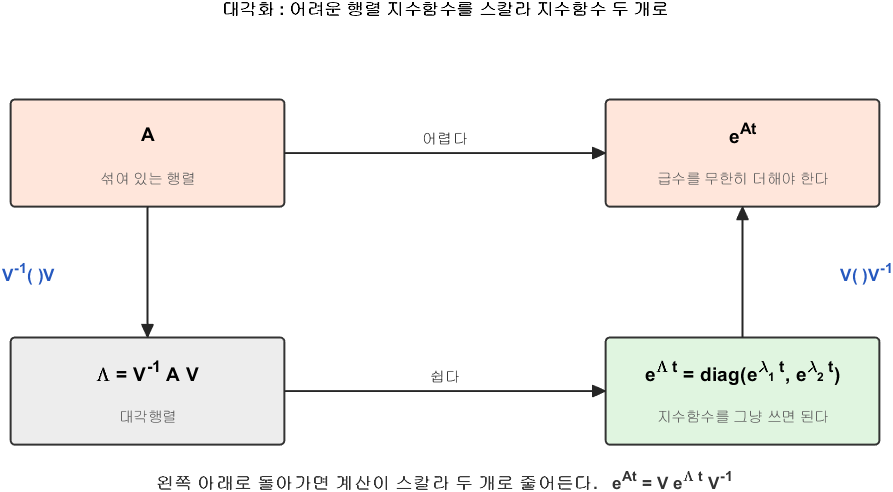

대각화하면 계산이 스칼라 두 개로 줄어든다

**그림 파일** `w12_diagonalize.png` — `make_figures.m` 의 `fig_w12_diagonalize` · 다시 만들려면 `make_figures('w12_diagonalize')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_diagonalize` **직접 확인해 보려면** — `W12_01_state_response.m` 의 **3절**이 `expm(A*t)` 와 $V e^{\Lambda t} V^{-1}$ 이 같은지 대조합니다

그림 해석

**위로 곧장 가지 말고 아래로 돌아가라**는 것이 이 그림의 전부입니다. 돌아가는 길이 오히려 짧습니다.

## 3-1. 오늘의 새 명령 세 개 — `eig`, `expm`, `poly`

`eig` — **고유값과 고유벡터**

- **하는 일** — $Av = \lambda v$ 를 만족하는 $\lambda$ 와 $v$ 를 구한다

- **입력** — 정사각행렬 $A$

- **출력** — `eig(A)` 는 고유값 벡터. `[V, D] = eig(A)` 는 고유벡터 행렬 $V$ 와 고유값을 대각선에 놓은 $D$

주의

- 출력을 **하나만 받으면 고유값만** 나옵니다. 벡터가 필요하면 두 개로 받으십시오

- $V$ 의 **열**이 고유벡터입니다. 행이 아닙니다

- 고유벡터는 길이가 정해져 있지 않습니다. MATLAB 은 길이를 $1$ 로 맞춰 줍니다. 그래서 부호가 교과서와 반대로 나올 수 있는데 **틀린 것이 아닙니다**

`expm` — **행렬 지수함수** (2절에서 봤습니다)

- `exp` 와 혼동하지 마십시오. 반드시 `m` 을 붙입니다

`poly` — **특성다항식의 계수**

- **하는 일** — 행렬을 주면 $\left|sI - A\right|$ 의 계수를, 근의 목록을 주면 그 근을 갖는 다항식의 계수를 돌려준다

- **입력** — 행렬 $A$ 또는 근 벡터

- **출력** — 계수 벡터. $s$ 의 **높은 차수부터**

왜 유용한가 — "**고유값 **$=$** 전달함수의 극점**" 을 손으로 확인할 때 씁니다. `roots(poly(A))` 와 `eig(A)` 가 같은 답을 줍니다.

주의

- `poly` 와 `roots` 는 **서로 반대**입니다. `roots(poly(A))` 는 제자리로 돌아옵니다

- 차수가 높으면 계수를 거쳐 가는 동안 오차가 커집니다. 실무에서는 `eig` 를 직접 쓰고, `poly` 는 **확인용**으로만 씁니다

- 13주차에서 `poly([-8 -10 -12])` 처럼 **원하는 극점으로 특성다항식을 만들 때** 다시 씁니다

A_ex = [0 1; -2 -3];
fprintf('=== 세 명령이 같은 답을 준다 ===\n');

=== 세 명령이 같은 답을 준다 ===


fprintf('  eig(A)            : %s\n', mat2str(round(eig(A_ex).', 4)));

  eig(A)            : [-1 -2]


fprintf('  poly(A)           : %s   <- s^2 + 3s + 2 의 계수\n', ...
        mat2str(round(poly(A_ex), 4)));

  poly(A)           : [1 3 2]   <- s^2 + 3s + 2 의 계수


fprintf('  roots(poly(A))    : %s\n', mat2str(round(sort(roots(poly(A_ex))).', 4)));

  roots(poly(A))    : [-2 -1]


fprintf('  전달함수의 극점   : %s\n', ...
        mat2str(round(sort(pole(tf(ss(A_ex,[0;1],[1 0],0)))).', 4)));

  전달함수의 극점   : [-2 -1]


fprintf('  --> 넷이 같습니다. **고유값 = 극점** 이 이렇게 확인됩니다.\n\n');

  --> 넷이 같습니다. **고유값 = 극점** 이 이렇게 확인됩니다.



fprintf('=== 반대로도 됩니다 (13주차에서 씁니다) ===\n');

=== 반대로도 됩니다 (13주차에서 씁니다) ===


fprintf('  poly([-8 -10 -12]) : %s\n', mat2str(poly([-8 -10 -12])));

  poly([-8 -10 -12]) : [1 30 296 960]


fprintf('  즉 (s+8)(s+10)(s+12) = s^3 + 30s^2 + 296s + 960\n');

  즉 (s+8)(s+10)(s+12) = s^3 + 30s^2 + 296s + 960


[V0, D0] = eig(A0);
fprintf('고유값   : %s\n', mat2str(round(diag(D0).', 4)));

고유값   : [-1 -2]


fprintf('고유벡터 : %s\n', mat2str(round(V0, 4)));

고유벡터 : [0.7071 -0.4472;-0.7071 0.8944]


fprintf('V*expm(D*1)*inv(V) 와 expm(A*1) 의 차이 : %.2e\n', ...
        max(max(abs(V0*expm(D0*1)/V0 - expm(A0*1)))));

V*expm(D*1)*inv(V) 와 expm(A*1) 의 차이 : 1.11e-16


## 4. 모드 — 고유값 하나가 만드는 응답 조각

위 식을 풀어 쓰면 이렇게 됩니다.


$$x(t) = c_1\,e^{\lambda_1 t}\,v_1 + c_2\,e^{\lambda_2 t}\,v_2 + \cdots$$


각 항을 **모드**(mode)라고 부릅니다. 읽는 법은 이렇습니다.

- $e^{\lambda_i t}$ — **얼마나 빨리** 사그라드는가 (또는 커지는가)

- $v_i$ — **어느 방향으로** 그 일이 일어나는가

- $c_i$ — 초기조건에 그 모드가 **얼마나 섞여 있는가**

계수는 좌표변환 한 줄로 나옵니다.


$$c = V^{-1}x(0)$$


**모든 응답은 모드의 합**입니다. 이것이 오늘의 첫 번째 큰 그림입니다.

## 4-1. 고유벡터 방향에서 출발하면

만약 $x(0)$ 가 고유벡터 $v_1$ 과 정확히 같은 방향이라면 $c_2 = 0$ 이 되어 모드 하나만 남습니다.


$$x(t) = c_1\,e^{\lambda_1 t}\,v_1$$


즉 **응답이 지수함수 하나**가 됩니다. 방향도 안 변합니다. 상태평면에서 보면 원점을 향해 **직선으로** 갑니다.

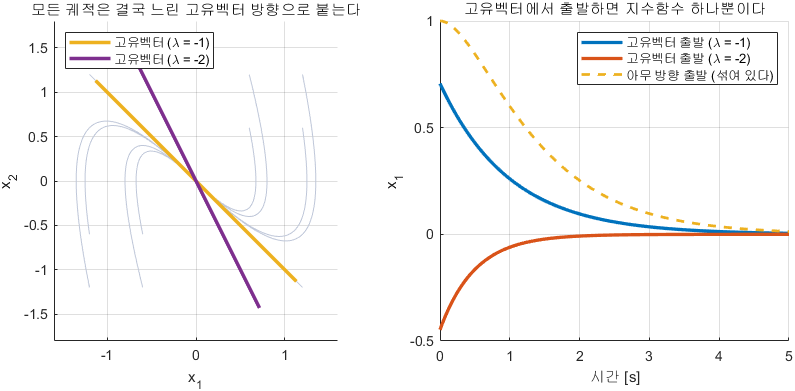

고유벡터 위에서 출발하면 직선, 아니면 휜다

**그림 파일** `w12_modes.png` — `make_figures.m` 의 `fig_modes` · 다시 만들려면 `make_figures('w12_modes')`

**만드는 곳** — `make_figures.m` 의 `fig_modes` **직접 확인해 보려면** — `W12_03_run_simulink.m` 의 **2절**이 Simulink 로 같은 실험을 하고 이론값과 대조합니다

그림 해석

왼쪽 그림의 **"결국 노란 직선에 붙는다"** 가 오늘의 핵심 관찰입니다. 4주차에서 말한 **지배극점**이 상태공간에서는 이렇게 설명됩니다.

## 5. 안정성 — 고유값 하나만 봐도 된다

모드가 합으로 되어 있으니 결론이 간단합니다.


$$\text{안정이다} \quad\Rightarrow\quad \text{모든 고유값의 실수부가 음수}$$



$$\text{모든 고유값의 실수부가 음수} \quad\Rightarrow\quad \text{안정이다}$$


양쪽이 다 성립하므로 **둘은 같은 말**입니다.

- 하나라도 실수부가 양수면 그 모드가 커진다

- 나머지가 아무리 안정해도 소용없다. **합이 발산한다**

그리고 3주차에서 확인했듯이 **고유값 **$=$** 전달함수의 극점**입니다. 즉 지금까지 극점으로 판단하던 것과 완전히 같은 이야기입니다.

고유값이 $s$ 평면 어디에 있으면 응답이 어떻게 생기는지를 한 장에 모았습니다. **이 그림 하나만 외우면 오늘의 절반은 끝납니다.**

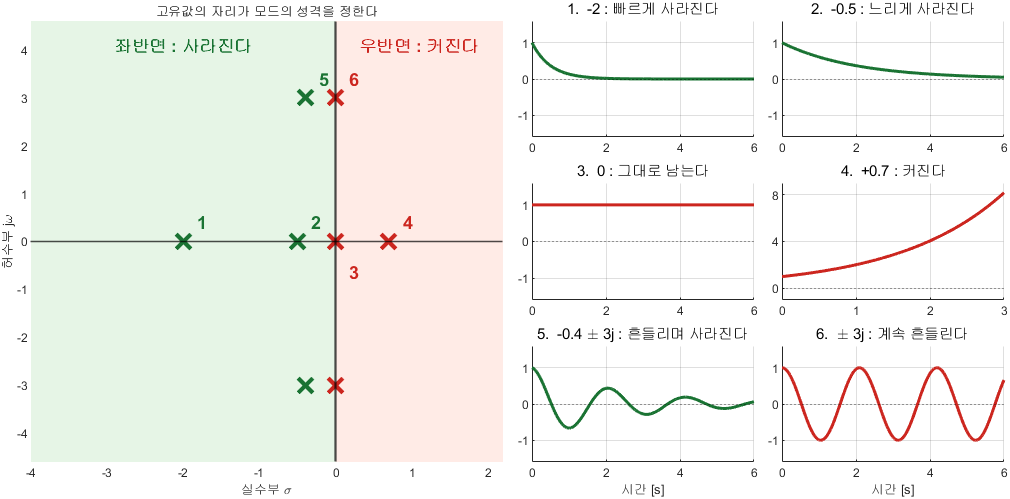

고유값의 자리와 그 모드의 거동

**그림 파일** `w12_eig_map.png` — `make_figures.m` 의 `fig_w12_eig_map` · 다시 만들려면 `make_figures('w12_eig_map')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_eig_map` **직접 확인해 보려면** — `W12_01_state_response.m` 의 **4-1절**이 불안정한 예제로 같은 확인을 합니다

그림 해석

마지막 줄이 핵심입니다. 두 축이 서로 다른 것을 정합니다.

- **실수부** — 커지는가 사라지는가, 그리고 얼마나 빠른가

- **허수부** — 흔들리는가, 그리고 얼마나 빠르게 흔들리는가

**다만 한 가지가 다릅니다.** 전달함수에서 상쇄로 사라진 극점도 고유값 목록에는 남아 있습니다. 그래서 상태공간 쪽이 **더 정직합니다.** 12절에서 다시 다룹니다.

## 6. 유사변환 — 좌표를 바꿔도 시스템은 같다

상태를 $z = T^{-1}x$ 로 바꿔 보겠습니다. 그러면


$$\dot{z} = T^{-1}A T\,z + T^{-1}B\,u, \qquad y = C T\,z + D u$$


즉 $(A,B,C,D)$ 가 $(T^{-1}AT,\; T^{-1}B,\; CT,\; D)$ 로 바뀝니다. **행렬은 완전히 달라 보이는데 시스템은 그대로입니다.**

무엇이 안 바뀌는가

- **고유값** — 특성다항식 $\left|T^{-1}AT - \lambda I\right|$ 가 $\left|A - \lambda I\right|$ 와 같기 때문

- **전달함수** — 입출력 관계는 좌표와 무관하다

- **가제어성·가관측성** — 오늘 배울 두 판정도 안 바뀐다

무엇이 바뀌는가

- $A, B, C$ 의 **숫자들**

- 상태 $x$ 의 **물리적 의미**

그래서 **상태공간 표현은 하나가 아닙니다.** 무한히 많습니다. 3주차에서 만든 것은 그중 하나(가제어 표준형에 가까운 것)일 뿐입니다.

실무에서는 목적에 맞는 좌표를 골라 씁니다. 대각화하면 모드가 보이고, 가제어 표준형으로 바꾸면 13주차 극배치가 쉬워집니다.

가장 유용한 좌표는 $T = V$ (고유벡터를 열로 쌓은 행렬)입니다. 이때 $V^{-1}AV = \Lambda$ 가 대각행렬이 되어 상태방정식이


$$\dot{z}_i = \lambda_i z_i \qquad (i = 1, 2)$$


처럼 **서로 얽히지 않은 1차 방정식 두 개**로 갈라집니다. 각 $z_i$ 는 $z_i(0)e^{\lambda_i t}$ 로 혼자 움직입니다.

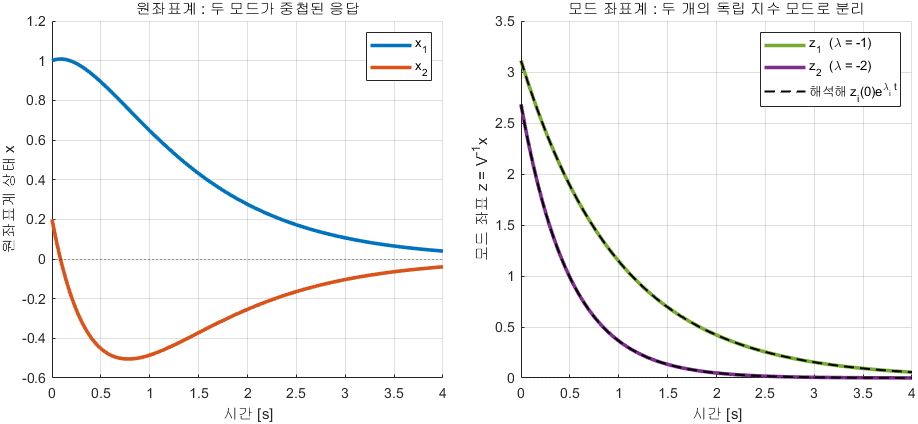

좌표를 바꾸면 모드가 분리된다

**그림 파일** `w12_similarity.png` — `make_figures.m` 의 `fig_w12_similarity` · 다시 만들려면 `make_figures('w12_similarity')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_similarity` **직접 확인해 보려면** — `W12_01_state_response.m` 의 **3-1절**이 `[V,D] = eig(A)` 로 대각화하고 고유값이 보존되는지 확인합니다

그림 해석

좌표를 바꿔도 **고유값은 그대로**입니다. 바뀐 것은 상태를 어떤 축으로 쪼개 보느냐 뿐입니다.

[Gm, pm] = plant_msd();
sys1 = ss(pm.A, pm.B, pm.C, pm.D);
T = [1 1; 0 2];
sys2 = ss(T\pm.A*T, T\pm.B, pm.C*T, pm.D);
fprintf('원래 A   : %s,  고유값 %s\n', mat2str(round(pm.A,3)), ...
        mat2str(round(eig(pm.A).', 3)));

원래 A   : [0 1;-1 -0.2],  고유값 [-0.1+0.995i -0.1-0.995i]


fprintf('바꾼 A   : %s,  고유값 %s\n', mat2str(round(sys2.A,3)), ...
        mat2str(round(eig(sys2.A).', 3)));

바꾼 A   : [0.5 2.7;-0.5 -0.7],  고유값 [-0.1+0.995i -0.1-0.995i]


fprintf('두 전달함수의 극점 차이 : %.2e\n', ...
        max(abs(sort(pole(tf(sys1))) - sort(pole(tf(sys2))))));

두 전달함수의 극점 차이 : 8.33e-17


## 7. 가제어성 — 입력으로 모든 상태를 움직일 수 있는가

이제 오늘의 두 번째 큰 주제입니다.

13주차에서 우리는 **고유값을 원하는 자리로 옮기려고** 합니다. 그런데 옮길 수 없는 경우가 있습니다. 입력이 그 상태를 못 미는 경우입니다.

정의는 이렇습니다.

- 어떤 초기 상태에서 출발하든, **유한한 시간 안에** 원하는 상태로 데려갈 수 있는 입력이 존재하면 그 시스템은 **가제어**하다

판정은 행렬 하나의 계수를 보면 끝납니다.


$$\mathcal{C} = \left[\begin{array}{cccc} B & AB & A^2B & \cdots \end{array}\right], \qquad \mathrm{rank}(\mathcal{C}) = n \;\Rightarrow\; \text{가제어}$$


## 7-1. 왜 그 행렬인가 — 직관

각 열이 무엇을 뜻하는지 보면 자연스럽습니다.

즉 **입력 하나로 만들어 낼 수 있는 방향을 전부 모은 것**입니다. 그 방향들이 $n$ 차원 공간을 다 덮으면(계수 $n$) 어디든 갈 수 있습니다.

열이 $n$ 개까지만인 이유는 케일리-해밀턴 정리 때문입니다. $A^n$ 부터는 앞의 것들의 조합으로 표현되어 **새 방향이 안 나옵니다.**

상태가 둘뿐이면 이것을 그림으로 볼 수 있습니다.

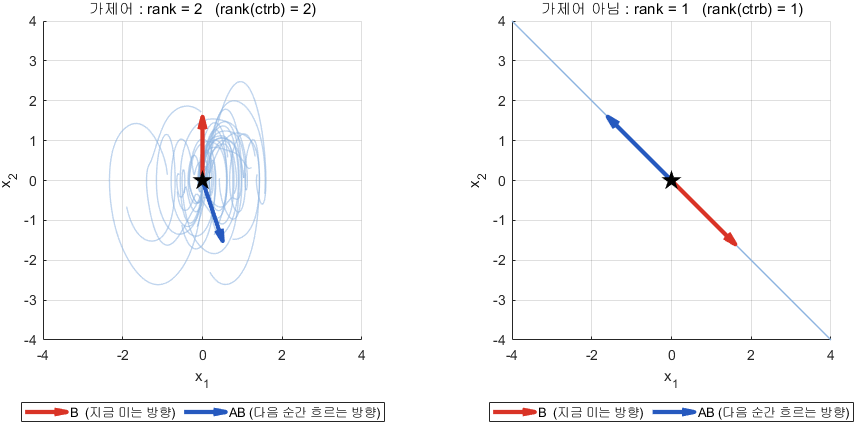

B 와 AB 가 평면을 덮는가

**그림 파일** `w12_reach.png` — `make_figures.m` 의 `fig_w12_reach` · 다시 만들려면 `make_figures('w12_reach')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_reach` **직접 확인해 보려면** — `W12_02_ctrb_obsv.m` 의 **1절**이 같은 두 경우의 계수를 계산합니다

그림 해석

오른쪽 그림이 "가제어가 아니다" 의 정확한 뜻입니다. 상태가 **안 움직이는 것이 아니라, 정해진 방향으로만 움직이는 것**입니다. 그 직선 밖으로는 아무리 큰 입력을 넣어도 나갈 수 없습니다.

## 7-2. `ctrb` — 오늘의 새 명령

명령 정리

- **하는 일** — 가제어성 행렬 $[B\;\;AB\;\;\cdots]$ 를 만들어 준다

- **입력** — `ctrb(A, B)` 또는 `ctrb(sys)`

- **출력** — $n \times (n\cdot m)$ 행렬. 판정은 `rank` 로 따로 한다

주의 두 가지

- `ctrb` 는 **판정을 안 해 줍니다.** 반드시 `rank` 를 씌워야 합니다

- 차수가 높으면 $A^{n-1}B$ 가 아주 커져 **수치적으로 위험**하다. $n$ 이 $10$ 을 넘으면 `ctrbf` 나 `minreal` 을 쓰는 편이 낫다

예제 — 대각행렬이라 두 상태가 서로 무관한 시스템에서

Ac = [-1 0; 0 -2];
for B = {[1;1], [1;0]}
    r = rank(ctrb(Ac, B{1}));
    fprintf('B = %-8s : ctrb = %-14s rank = %d -> %s\n', ...
            mat2str(B{1}.'), mat2str(ctrb(Ac, B{1})), r, ...
            string(r == 2).replace("true","가제어").replace("false","가제어 아님"));
end

B = [1 1]    : ctrb = [1 -1;1 -2]    rank = 2 -> 가제어
B = [1 0]    : ctrb = [1 -1;0 0]     rank = 1 -> 가제어 아님


## 8. 가제어가 아니면 실제로 무슨 일이 생기는가

판정만 하면 와닿지 않으니 직접 돌려 봅니다. 같은 계단 입력을 넣고 상태 두 개를 모두 그린 것입니다.

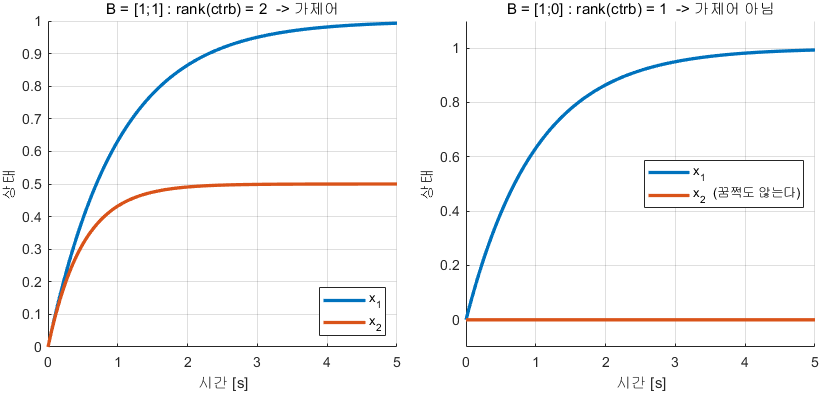

입력이 못 미는 상태는 꿈쩍도 하지 않는다

**그림 파일** `w12_ctrb.png` — `make_figures.m` 의 `fig_ctrb` · 다시 만들려면 `make_figures('w12_ctrb')`

**만드는 곳** — `make_figures.m` 의 `fig_ctrb` **직접 바꿔 보려면** — `W12_02_ctrb_obsv.m` 의 **2절**에서 `A` 의 비대각 원소를 $0$ 이 아닌 값으로 바꿔 보십시오. 가제어가 됩니다

그림 해석

여기서 배울 것 — **가제어가 아니면 그 상태의 고유값은 영원히 그 자리입니다.** 13주차의 `place` 는 이런 시스템에서 오류를 냅니다. 그 고유값이 우반면에 있다면 **그 시스템은 안정화가 불가능**합니다.

## 9. 진자는 가제어인가

12~14주차의 주인공은 **거꾸로 선 진자**입니다. 3주차에서 만든 그 진자를 $\theta_0 = 180^\circ$ 에서 선형화한 것입니다.

상태는 둘입니다 — 각도와 각속도. 입력은 하나 — 축에 거는 토크.

토크 하나로 각도와 각속도를 **둘 다** 원하는 대로 만들 수 있는가?

[sysUp, pUp] = plant_pendulum(pi);
fprintf('=== 거꾸로 선 진자 ===\n');

=== 거꾸로 선 진자 ===


fprintf('  A = %s\n', mat2str(round(pUp.A, 3)));

  A = [0 1;32.7 0]


fprintf('  B = %s\n', mat2str(round(pUp.B, 3)));

  B = [0;22.222]


fprintf('  고유값 : %s   <- 하나가 양수. 개루프 불안정\n', ...
        mat2str(round(eig(pUp.A).', 3)));

  고유값 : [5.718 -5.718]   <- 하나가 양수. 개루프 불안정


fprintf('  ctrb   = %s\n', mat2str(round(ctrb(pUp.A, pUp.B), 3)));

  ctrb   = [0 22.222;22.222 0]


fprintf('  rank   = %d / 2  ->  가제어\n', rank(ctrb(pUp.A, pUp.B)));

  rank   = 2 / 2  ->  가제어


## 9-1. 왜 가제어인가 — 손으로 확인

진자의 $A$ 와 $B$ 는 이렇게 생겼습니다.


$$A = \left[\begin{array}{cc} 0 & 1\\ \frac{mgl}{J} & -\frac{b}{J}\end{array}\right], \qquad B = \left[\begin{array}{c} 0\\ \frac{1}{J}\end{array}\right]$$


가제어성 행렬을 만들면


$$\mathcal{C} = \left[\begin{array}{cc} B & AB \end{array}\right] = \left[\begin{array}{cc} 0 & \frac{1}{J}\\ \frac{1}{J} & -\frac{b}{J^2}\end{array}\right]$$


행렬식이 $-1/J^2$ 이고 $J \ne 0$ 이므로 **항상 가제어**입니다.

물리적으로 읽으면 — 토크는 각속도를 직접 밉니다($B$ 의 둘째 성분). 그리고 각속도가 변하면 각도가 따라 변합니다($A$ 의 첫째 줄 $[0\;\;1]$). 그래서 **토크 하나로 둘 다 조종할 수 있습니다.**

13주차를 진행할 수 있다는 뜻입니다.

## 10. 가관측성 — 출력만 보고 상태를 알 수 있는가

이제 반대편입니다.

14주차에서 우리는 **못 재는 상태를 만들어 내려고** 합니다. 그런데 만들어 낼 수 없는 경우가 있습니다. 출력에 그 정보가 안 나오는 경우입니다.

정의는 가제어성과 짝을 이룹니다.

- 유한한 시간 동안 $y(t)$ 와 $u(t)$ 를 지켜본 것만으로 초기 상태 $x(0)$ 를 알아낼 수 있으면 **가관측**하다

판정 행렬도 짝입니다.


$$\mathcal{O} = \left[\begin{array}{c} C \\ CA \\ CA^2 \\ \vdots\end{array}\right], \qquad \mathrm{rank}(\mathcal{O}) = n \;\Rightarrow\; \text{가관측}$$


직관 — $C$ 는 지금 보이는 것, $CA$ 는 그 변화율에 담긴 정보, $CA^2$ 는 또 그 변화율입니다. **출력과 그 미분들을 다 모으면 상태를 복원할 수 있는가**를 묻는 것입니다.

## 10-1. `obsv` — 오늘의 새 명령

명령 정리

- **하는 일** — 가관측성 행렬을 세로로 쌓아 만들어 준다

- **입력** — `obsv(A, C)` 또는 `obsv(sys)`

- **출력** — $(n\cdot p) \times n$ 행렬. 판정은 `rank` 로 따로

주의

- `ctrb` 는 **가로로**, `obsv` 는 **세로로** 쌓습니다. 혼동하지 마십시오

- 역시 판정을 안 해 주므로 `rank` 를 씌워야 합니다

쌍대성 — 두 판정은 사실 같은 문제입니다.


$$\mathrm{rank}\,\mathcal{O}(A, C) = \mathrm{rank}\,\mathcal{C}(A^{T}, C^{T})$$


즉 $(A, C)$** 의 가관측성은 **$(A^{T}, C^{T})$** 의 가제어성과 같습니다.** 14주차에서 관측기 이득을 `place(A', C', p)'` 로 구하는 이유가 바로 이것입니다.

## 11. 가관측이 아니면 무슨 일이 생기는가

초기조건을 서로 다르게 주고 출력이 구별되는지 봅니다.

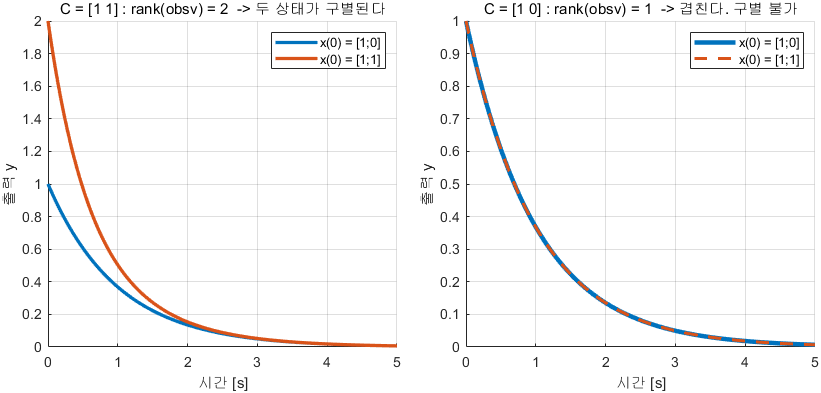

구별이 안 되면 추정도 안 된다

**그림 파일** `w12_obsv.png` — `make_figures.m` 의 `fig_obsv` · 다시 만들려면 `make_figures('w12_obsv')`

**만드는 곳** — `make_figures.m` 의 `fig_obsv` **직접 바꿔 보려면** — `W12_02_ctrb_obsv.m` 의 **3절**에서 `C` 를 바꿔 실행

그림 해석

여기서 배울 것 — **출력이 같으면 안쪽이 달라도 알 방법이 없습니다.** 14주차의 관측기는 이런 상태를 추정할 수 없습니다. 그 상태가 불안정하다면 **모르는 채로 발산하는 것을 지켜봐야** 합니다.

## 12. 진자에서 무엇을 재야 하는가

센서를 하나만 달 수 있다면 무엇을 측정해야 하는가?

상태는 각도와 각속도 둘입니다. 후보는 셋입니다.

- 각도계만 — $C = [1\;\;0]$

- 자이로만 — $C = [0\;\;1]$

- 둘 다 — $C = I$

하나씩 판정해 봅니다.

Cs = { '각도만  C = [1 0]',  [1 0]
       '각속도만 C = [0 1]', [0 1]
       '둘 다   C = eye(2)', eye(2) };
fprintf('=== 센서 선택별 가관측성 ===\n');

=== 센서 선택별 가관측성 ===


for k = 1:3
    r = rank(obsv(pUp.A, Cs{k,2}));
    fprintf('  %-20s rank = %d / 2  ->  %s\n', Cs{k,1}, r, ...
            string(r == 2).replace("true","가관측").replace("false","가관측 아님"));
end

  각도만  C = [1 0]       rank = 2 / 2  ->  가관측
  각속도만 C = [0 1]       rank = 2 / 2  ->  가관측
  둘 다   C = eye(2)     rank = 2 / 2  ->  가관측


셋 다 가관측입니다. **각도 하나만 재도 됩니다.**

왜 그런가 — $A$ 의 첫 줄이 $[0\;\;1]$ 이라 각도의 미분이 각속도입니다. 각도를 계속 지켜보고 있으면 그 **기울기**에서 각속도를 알 수 있습니다. 그래서 각도계 하나로 두 상태를 다 복원할 수 있습니다.

실무적으로 중요한 결론입니다 — **센서를 하나만 달아도 됩니다.** 각속도계를 추가로 다는 것은 잡음이 적은 추정을 얻기 위한 선택이지, 필수가 아닙니다. 14주차에서 각도계 하나로 관측기를 만듭니다.

## 12-1. 상쇄가 일어나면 무엇이 사라지는가

가제어·가관측이 깨지는 가장 흔한 원인이 **극점과 영점의 상쇄**입니다.

7주차에서 "불안정한 극점을 상쇄하면 절대 안 된다" 고 했습니다. 그 이유가 오늘 정확히 나옵니다.

상쇄가 일어나면 그 모드는 **전달함수에서 사라집니다.** 그런데 상태공간에는 그대로 남아 있습니다. 없어진 것이 아닙니다.

- 상쇄된 모드가 **안정**하면 — 안 보여도 스스로 죽으니 괜찮다

- 상쇄된 모드가 **불안정**하면 — 안 보이는 채로 발산한다. **재앙이다**

7주차에서 본 그 예제를 이번에는 고유값으로 설명하겠습니다. 불안정 플랜트 $G = 1/(s-1)$ 에 제어기 $C = 7(s-1)/(s+4)$ 를 붙여 우반면 극점을 상쇄한 경우입니다.

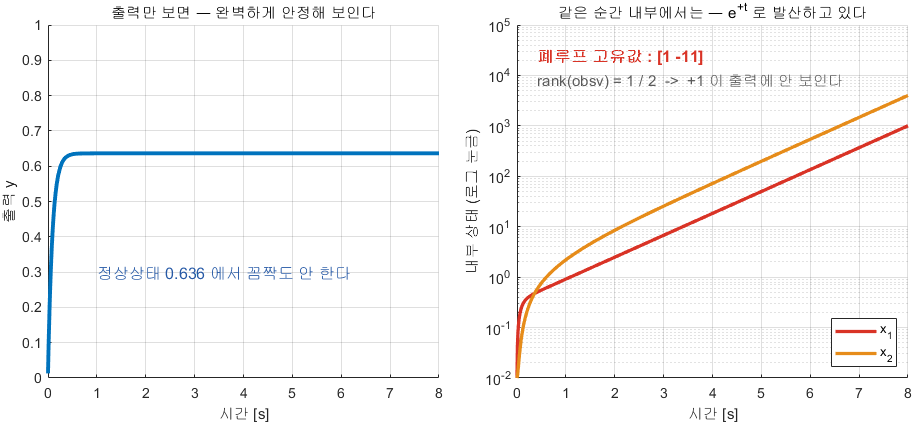

출력에는 안 보이는 채로 상태가 발산한다

**그림 파일** `w12_hidden_mode.png` — `make_figures.m` 의 `fig_w12_hidden_mode` · 다시 만들려면 `make_figures('w12_hidden_mode')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_hidden_mode` **직접 확인해 보려면** — `W07_03_pd_design_practice.m` 의 **3-1절**이 같은 예제를 외란으로 드러냅니다. 오늘은 그것을 고유값으로 설명한 것입니다

그림 해석

**왼쪽 그림이 이 절의 경고입니다.** 계단응답만 보고 안정하다고 판단하면 안 됩니다. 반드시 `eig(A)` 로 **고유값을 직접 확인**하십시오. 전달함수는 상쇄된 것을 안 보여 주지만, 고유값은 전부 보여 줍니다.

MATLAB 의 `minreal` 이 하는 일이 바로 그 사라진 부분을 떼어내는 것입니다. 떼어낸 만큼이 **가제어도 가관측도 아닌 부분**입니다.

sys_full = ss([-1 0; 0 -2], [1;1], [1 0], 0);
fprintf('원래 상태 %d 개, 고유값 %s\n', size(sys_full.A,1), ...
        mat2str(round(eig(sys_full.A).', 3)));

원래 상태 2 개, 고유값 [-2 -1]


fprintf('전달함수의 극점 : %s\n', mat2str(round(pole(tf(sys_full)).', 3)));

전달함수의 극점 : -1


sys_min = minreal(sys_full);

1 state removed.


fprintf('minreal 후 상태 %d 개  -> %d 개가 숨어 있었다\n', ...
        size(sys_min.A,1), size(sys_full.A,1) - size(sys_min.A,1));

minreal 후 상태 1 개  -> 1 개가 숨어 있었다


## 13. 오늘 판정한 것이 다음 두 주의 입장권이다

오늘 배운 두 판정이 왜 중요한지 정리합니다.

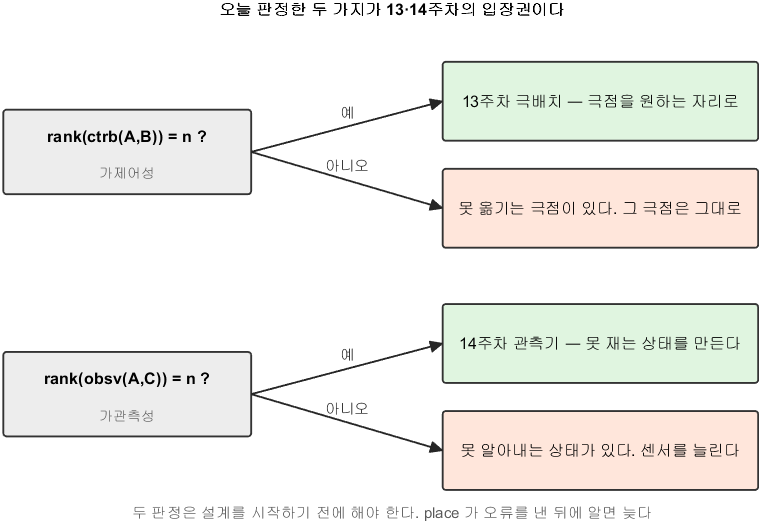

두 판정이 갈라 놓는 네 갈래

**그림 파일** `w12_gateway.png` — `make_figures.m` 의 `fig_w12_gateway` · 다시 만들려면 `make_figures('w12_gateway')`

**만드는 곳** — `make_figures.m` 의 `fig_w12_gateway` **직접 확인해 보려면** — `W12_02_ctrb_obsv.m` 이 오늘 다룬 모든 예제를 이 두 질문으로 판정합니다

그림 해석

마지막 줄을 조심하십시오. **둘은 별개의 판정입니다.** $B$ 가 정하는 것과 $C$ 가 정하는 것이 다르기 때문입니다. 하나가 통과했다고 다른 하나가 따라오지 않습니다.

그리고 두 판정이 **부분적으로** 깨질 수도 있습니다.

- **안정화 가능**(stabilizable) — 가제어가 아닌 모드가 **이미 안정**하다. 못 옮기지만 어차피 스스로 죽으므로 실용상 괜찮다

- **검출 가능**(detectable) — 가관측이 아닌 모드가 이미 안정하다. 마찬가지

실무에서 실제로 확인해야 하는 것은 이 둘입니다. **못 만지는 모드가 불안정하기만 하면 안 됩니다.**

## 14. Simulink 로 모드를 눈으로 보기

모델 `W12_StateSpace_Modes.slx` 를 열어 보십시오. 블록이 셋뿐입니다.

그런데 `State-Space` 블록에는 `Transfer Fcn` 블록에 **없는 칸**이 있습니다.

- `Initial conditions` — 초기조건

전달함수는 초기조건이 $0$ 이라는 가정 위에서 유도한 것이라 이 칸이 없습니다. 3주차에서 "물체를 당겨 놓고 놓았을 때 전달함수는 답을 못 한다" 고 했던 바로 그 이야기입니다.

오늘은 **입력을 아예 **$0$** 으로 두고 초기조건만으로** 시스템을 움직입니다.

`W12_03_run_simulink.m` 을 실행하면 다음을 확인합니다.

- 고유벡터 방향에서 출발하면 응답이 **지수함수 하나** (이론과 $10^{-13}$ 이내로 일치)

- 아무 방향이면 **두 모드의 합**

- 불안정한 모드가 있으면 아주 살짝만 틀어도 결국 발산

## 14-1. 오늘 나온 명령을 여러 가지로 써 본다

상태공간 해석에 쓰는 명령들은 **출력을 몇 개 받느냐**로 하는 일이 갈립니다.

`exp` **와** `expm` **은 완전히 다릅니다.** `exp(A)` 는 성분마다 지수를 취하고, `expm(A)` 는 행렬 지수함수입니다. 우리가 필요한 것은 언제나 `expm` 입니다.

[~, pA] = plant_dcmotor('position');
Am = pA.A;  Bm = pA.B;  Cm = pA.C;

[Vm, Dm] = eig(Am);
fprintf('고유값 : %s\n', mat2str(round(diag(Dm).', 4)));

고유값 : [0 -9.9975 -2.0025]



% expm 이 정말 고유분해와 같은지 확인
tq = 0.1;
E_direct = expm(Am*tq);
E_eigen  = real(Vm * diag(exp(diag(Dm)*tq)) / Vm);
fprintf('expm 과 고유분해의 최대 차이 : %.2e\n', max(abs(E_direct(:) - E_eigen(:))));

expm 과 고유분해의 최대 차이 : 2.22e-16



% 특성다항식으로 돌아가도 같은 고유값이 나온다
fprintf('poly(A) = %s\n', mat2str(round(poly(Am), 4)));

poly(A) = [1 12 20.02 0]


fprintf('roots(poly(A)) 와 eig(A) 의 차이 : %.2e\n', ...
        max(abs(sort(roots(poly(Am))) - sort(eig(Am)))));

roots(poly(A)) 와 eig(A) 의 차이 : 0.00e+00



% 판정은 언제나 rank 로
fprintf('\nrank(ctrb) = %d / %d  -> %s\n', rank(ctrb(Am,Bm)), size(Am,1), ...
        string(rank(ctrb(Am,Bm))==size(Am,1)) + " (가제어)");


rank(ctrb) = 3 / 3  -> true (가제어)


fprintf('rank(obsv) = %d / %d  -> %s\n', rank(obsv(Am,Cm)), size(Am,1), ...
        string(rank(obsv(Am,Cm))==size(Am,1)) + " (가관측)");

rank(obsv) = 3 / 3  -> true (가관측)


## 15. 오늘의 정리

- 상태방정식의 해는 $x(t) = e^{At}x(0) + \int e^{A(t-\tau)}Bu\,d\tau$

- `expm` 과 `exp` 는 다르다. 반드시 **m 을 붙일 것**

- $A = V\Lambda V^{-1}$ 로 대각화하면 스칼라 문제로 쪼개진다

- **모든 응답은 모드의 합**이다. 꼬리는 가장 느린 모드가 정한다

- 고유값 하나라도 실수부가 양수면 불안정

- 좌표를 바꿔도(유사변환) 고유값과 전달함수는 안 바뀐다

- **가제어** `rank(ctrb(A,B)) = n` — 입력으로 모든 상태를 움직일 수 있는가

- **가관측** `rank(obsv(A,C)) = n` — 출력만 보고 모든 상태를 알 수 있는가

- 거꾸로 선 진자는 가제어이고, **각도 하나만 재도 가관측**이다

- 상쇄된 모드는 사라진 것이 아니라 **숨은 것**이다

## 16. 다음 주 예고

13주차에서는 **극배치**를 합니다.

지금까지 우리는 $K$ 하나로 이득만 조절했고, 극점은 근궤적이라는 **정해진 길** 위에서만 움직일 수 있었습니다.

상태궤환 $u = -Kx$ 를 쓰면 이야기가 달라집니다.

- 극점을 **길과 상관없이 원하는 자리에 정확히** 놓을 수 있다

- 조건은 하나 — **가제어일 것**. 오늘 확인했습니다

거꾸로 선 진자를 실제로 세웁니다. 개루프 불안정 극점 $+5.72$ 를 좌반면으로 옮기는 것입니다.

물론 공짜가 아닙니다. **극을 왼쪽으로 보낼수록 제어입력이 커집니다.** 6주차와 7주차에서 본 그 교훈이 여기서도 그대로 나옵니다.